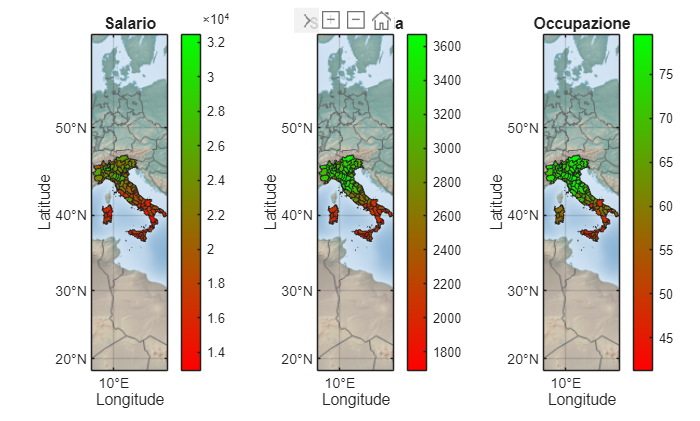

load citiesItaly2024.mat
GT = citiesItaly2024.Properties.UserData{1};
GT1 = [GT citiesItaly2024];
tiledlayout(1,3);
sel = ["SalaryA","SpendingA" "Employm"];
titoli=["Salario" "Spesa media" "Occupazione"];
n = 256;
cmap = [linspace(1,0,n)' linspace(0,1,n)' zeros(n,1)]; 

for j = 1:length(sel)
    nexttile
    h = geoplot(GT1,'ColorVariable',sel(j));
    title(titoli(j))
    ax = gca;               
    colormap(ax, cmap)       

    v = GT1.(char(sel(j)));
    cmin = min(v);
    cmax = max(v);
    clim(ax, [cmin cmax])

    cb = colorbar(ax);

    geobasemap("colorterrain")
end